%Question 1
%a)
%declaring matrices
A = sym([
    -3 1;
    1 -4
    ])

$$A = \left(\begin{array}{cc} -3 & 1\\ 1 & -4 \end{array}\right)$$

B = [-2;9]

B =     -2
     9



%checking manual solutions
inv(A)

$$ans = \left(\begin{array}{cc} -\frac{4}{11} & -\frac{1}{11}\\ -\frac{1}{11} & -\frac{3}{11} \end{array}\right)$$

det(A)

$$ans = 11$$


%checking answer
inv(A)*B

$$ans = \left(\begin{array}{c} -\frac{1}{11}\\ -\frac{25}{11} \end{array}\right)$$

clear
%Question 1b)
A =[
    3 -4 -5;
    -7 1 -1;
    1 2 1
    ]

A =      3    -4    -5
    -7     1    -1
     1     2     1



B = [1;-6;6]

B =      1
    -6
     6



sym(inv(A)*B)

$$ans = \left(\begin{array}{c} \frac{31}{20}\\ \frac{31}{10}\\ -\frac{7}{4} \end{array}\right)$$

%Question 3)
%declaring variables
v = 12

v = 12

r1 = 160

r1 = 160

r2 = 270

r2 = 270

r3 = 330

r3 = 330

r4 = 360

r4 = 360

r5 = 75

r5 = 75


%declaring matrices
A = [
    0 r3+r1 r3 0;
    0 r3 r3+r2 0;
    0 0 0 r4+r5;
    1 -1 -1 -1
    ]

A =      0   490   330     0
     0   330   600     0
     0     0     0   435
     1    -1    -1    -1


B = [
    v;
    v;
    v;
    0;
    ]

B =     12
    12
    12
     0



inv(A)*B

ans =     0.0555
    0.0175
    0.0104
    0.0276


%Question 4)
clear
%declaring matrices
A = [
    1 0 0 0;
    1 4 16 64;
    1 7 49 343;
    1 10 100 1000
    ];

B = [
    1;
    -0.3971;
    0.3001;
    -0.2459
    ];

%calculating coefficients
coeff = inv(A)*B

coeff =     1.0000
   -1.1077
    0.2505
   -0.0152


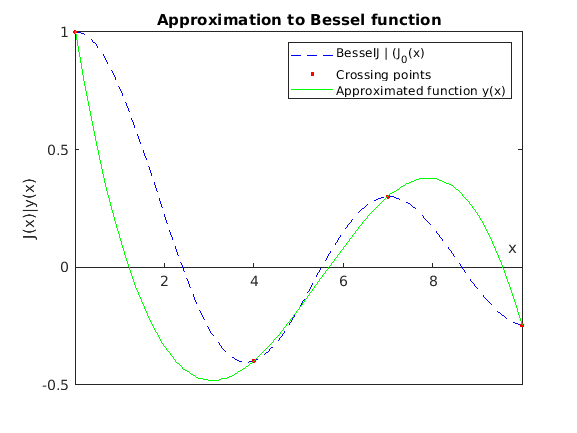


%calling a specfic row (rows, then columns)
coeff(1,1);
coeff(3,1);

%code from question
syms x %declaring symbolic variables

%equating coefficients
a0 = coeff(1,1);
a1 = coeff(2,1);
a2 = coeff(3,1);
a3 = coeff(4,1);

%declaring functions
y(x) = a0 + a1*x + a2*x^2 + a3*x^3; %calculated function
J(x) = besselj(0,x); %actual Bessel function

xred = [0 4 7 10]; %x points?
yred = eval(J(xred)); %corresponding bessel function y points

fplot(J,"--b","DisplayName","BesselJ | (J_0(x)") %plotting bessel func
hold on
plot(xred,yred,".r","DisplayName","Crossing points") %plotting crossing points
fplot(y(x),"g","DisplayName","Approximated function y(x)") %plotting calculated function
hold off

%setting ranges
xlim([0 10])
ylim([-1/2 1])

%beautiying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";

%labelling graph
xlabel("x")
ylabel("J(x)|y(x)")
title("Approximation to Bessel function")
legend("BesselJ | (J_0(x)","Crossing points","Approximated function y(x)")